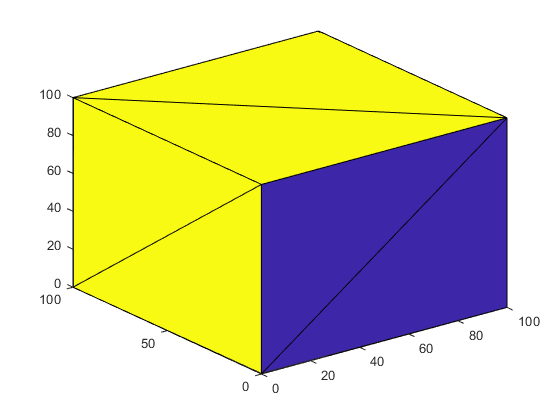

% Clear Workspace
clear all
clc

% Read STL File
% stl1 = stlread("Test Objects\cubeWithHole.STL");
% stl1 = stlread("Test Objects\cylinder.STL");
% stl1 = stlread("Test Objects\Case.STL");
stl1 = stlread("Test Objects\box.STL");
% stl1 = stlread("Test Objects\keys.STL");
% stl1 = stlread("Test Objects\Witcher_towel_hook.stl");

% Rotated stl
% rotatedSTL = stlRotate(stl1);
% rotatedSGO = FlatUniformSliceGenerator(rotatedSTL,10);
% rotatedSGO.generateSlices();
% op2 = rotatedSGO.getSlicePath();
trisurf(stl1)
hold on


% Create SliceGeneratorObject
sliceHeight = 0.5;
%sliceGen = FlatUniformSliceGenerator(stl1, sliceHeight)
sliceGen = FlatAdaptiveSliceGenerator(stl1, sliceHeight)

sliceGen =   FlatAdaptiveSliceGenerator with properties:

       layerProfiles: [4×3 double]
                 obj: []
    connectivityList: [12×3 double]
       numOfElements: 12
              points: [8×3 double]
      sliceThickness: 0.5000
           slicePath: []
           slicerTol: 1.0000e-05


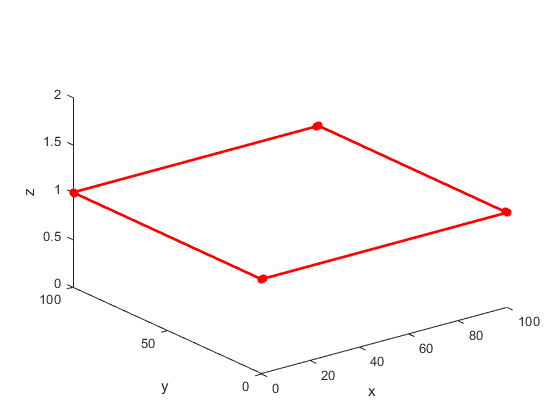


% Manual Slice for Debugging - Comment out if not used.
figure(2);
test = sliceGen.slicePathLayer(1);
for j = 1:max(test(:,4))

    pathPlotPoints = test(test(:,4) == j,:);
    plot3(pathPlotPoints(:,1), pathPlotPoints(:,2), pathPlotPoints(:,3),'-r*','LineWidth',2);
    hold on

end
xlabel('x');
ylabel('y');
zlabel('z');
view(3);

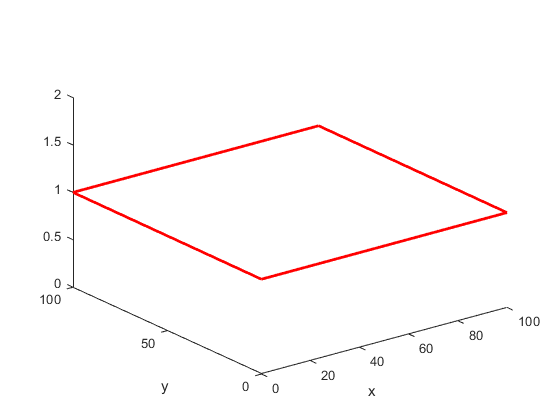


% Generate Full Slice Path
figure(3);
op = sliceGen.getSlicePath();
for i = 0:sliceHeight:double(max(op(:,3)))
    
    zPlotPoints = op(op(:,3) == i,:);
    for j = 1:max(zPlotPoints(:,4))
        pathPlotPoints = zPlotPoints(zPlotPoints(:,4) == j,:);
        plot3(pathPlotPoints(:,1), pathPlotPoints(:,2), pathPlotPoints(:,3),'-r','LineWidth',2);
        hold on
    end

end
xlabel('x')
ylabel('y')
view(3);


% Testing of Infill Generator
pathWithInfill = FlatSliceInfillGenerator(op, 20);